**What do the following have in common?...**

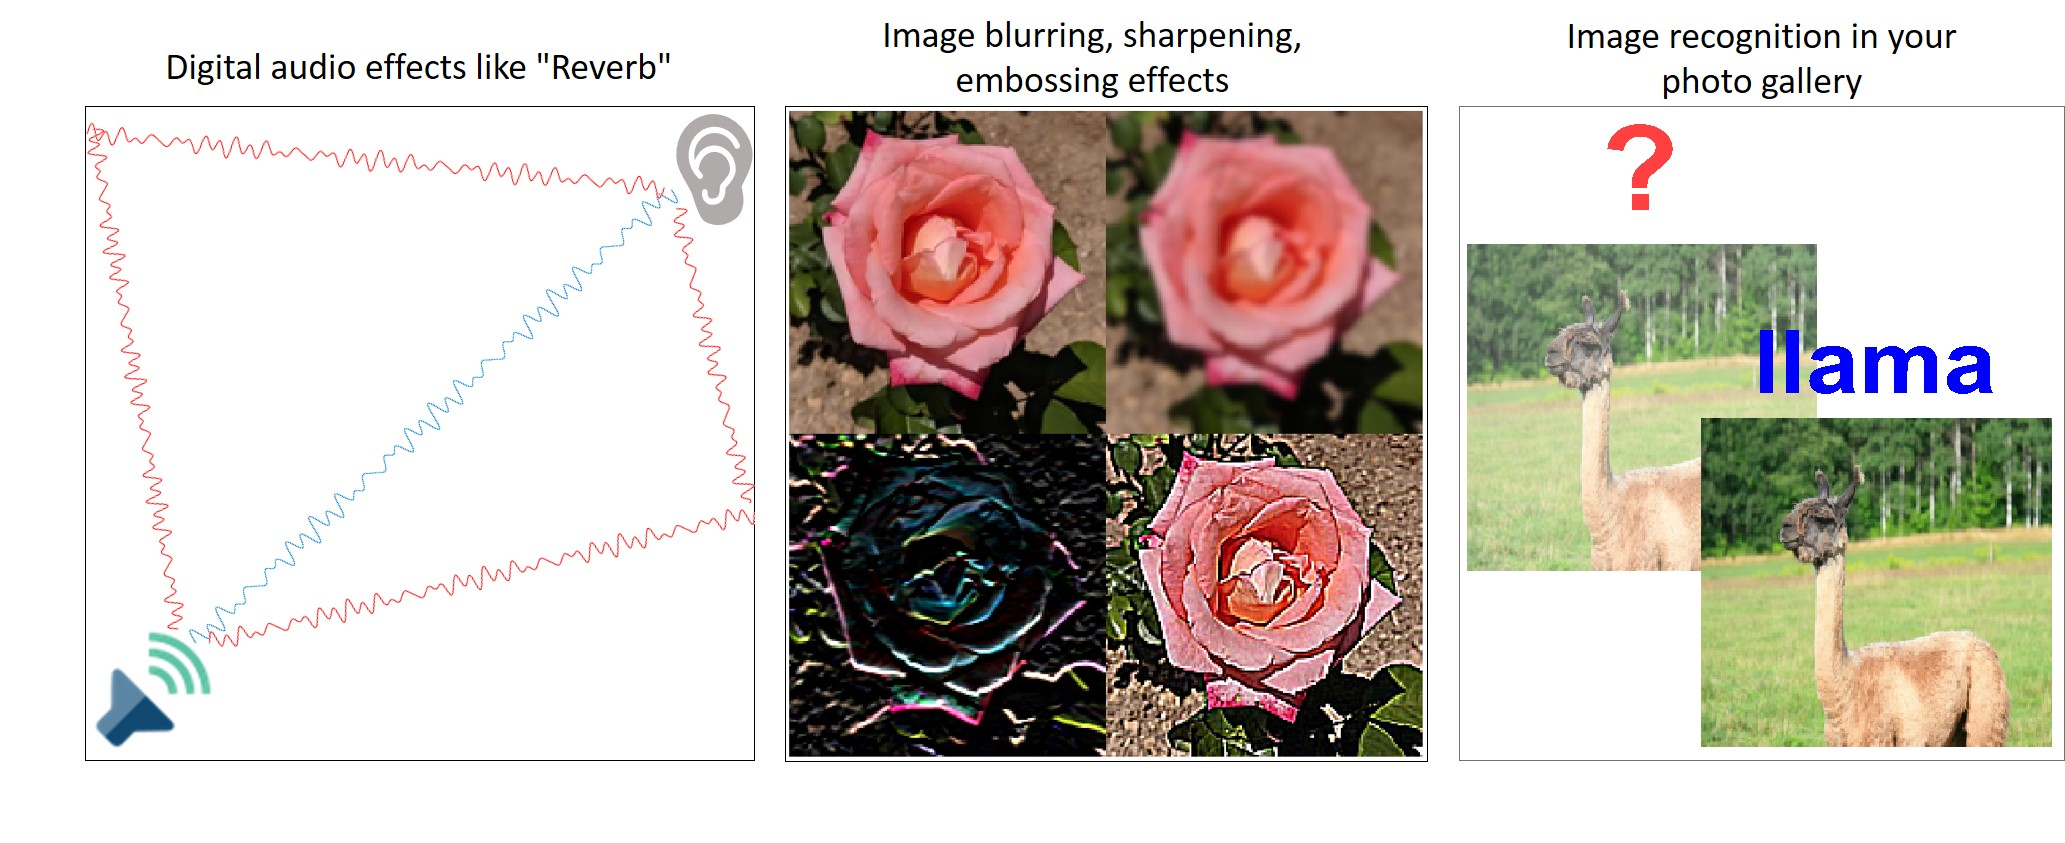

**... it's Convolution! **

# Convolution: Basics

## What is convolution?

The convolution of two continuous signals is another continuous signal. The value at some time `t `is defined as the integral of the products of the two input signals, where one of the signals has been shifted in time by `t` and flipped.

                                    
$$w\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)v\left(t-\tau \right)d\tau$$
  

Let's visualize this process with two simple pulse signals.

% Set up the time step and time (X) axis data.
ts = 1/1000;             % Time step
t = -3:ts:3;             % Time vector

Visit the documentation to learn more about the inputs to these functions: [rectpuls](https://www.mathworks.com/help/signal/ref/rectpuls.html), [tripuls](https://www.mathworks.com/help/signal/ref/tripuls.html)

***Task: ****Use the sliders and dropdowns to set different parameters for the signals. Click ****Run**** to view the convolution process and its result. *

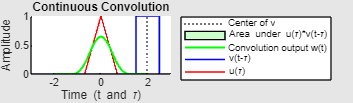

u  = tripuls(t,1.4) *1 ; % The first slider sets the width, the second slider scales the amplitude
v  = rectpuls(t,1) *1 ; % The first slider sets the width, the second slider scales the amplitude
 

animateConvolution(u,v,ts,t,-2);

This process is also called **linear convolution.**

***Try***

- *Change *`u`* to a rectangular pulse of width 1.5 and amplitude 1. *

- *Change *`v`* to a triangular pulse of width 1.5 and amplitude 1.*

- *Swap the *`u`* and *`v`* signal settings*`.`

- *Set *`u`* and *`v`* both to triangular pulse with different widths and amplitudes.*

- *Use the third input to set the skewness when using the triangular pulse signals.*

***Reflect***

- *Does the order of inputs matter? Is convolution commutative?*

- *Describe your general observations about the convolution output *`w`* compared to the inputs *`u`* and *`v`*? *

## Compute convolution

The animation above illustrates continuous convolution, which is defined as an integral. This was achieved by approximating a continuous result based on a discrete summation. Discrete convolution is defined by this summation:

                                    
$$w\left(k\right)=\sum_n u\left(n\right)\cdot v\left(k-n\right)$$


You can use the [`conv`](https://www.mathworks.com/help/releases/R2020a/matlab/ref/conv.html) function to compute the discrete convolution of two input sequences or discrete signals.

Let us define two 1-D discrete signals and convolve them using the `conv` function. 

***Task: ****Use the sliders and dropdowns to set different parameters for the two input signals.*

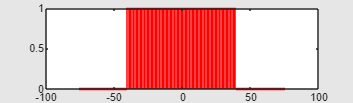

figure("Position",[0 0 1200 350], "Color", [0.9 0.9 0.9]);

L = 151;                   % length of input sequences u and v. Keep it odd for simplicity
n = -(L-1)/2:(L-1)/2;      % X axis data for the signals

u  = rectpuls(n,80);
stem(n,u,"r.")

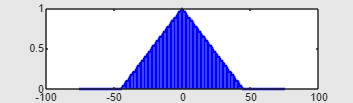

v  = tripuls(n,90);
stem(n,v,"b.")

We use the `conv` function to convolve two vectors in MATLAB.

w  =  conv(u, v);
disp("Output length = " + length(w))

Output length = 301


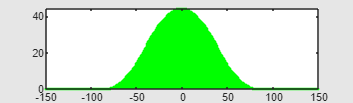

nOut = -(L-1):(L-1);
stem(nOut,w,"g.");

***Reflect***

- *How is the length of convolution output related to the length *`L`* of the two input signals? *

- *What do you think will happen if the input sequences had different lengths? say, *`M`* and *`N`*, instead of *`L`*.*

## **Helper function**

Function for creating the convolution animation.

function animateConvolution(f,h,ts,t,t0)

fs = 1/ts;
Cind = find(t == t0);   % Index of starting point in t
h_center = t0;

% Shift signal to extreme and flip
h = circshift(h,find(t==0) - Cind);
h = fliplr(h);

% Initialize plots for animation
figure("Position",[0 0 1200 350],"Color", [0.9 0.9 0.9]);
title("Continuous Convolution")
xlabel("Time (t and \tau)")
ylabel("Amplitude")

hold on
p0 = plot(t,f,"r","LineWidth",1.2);
p1 = plot(t,h,"b","LineWidth",1.2);
p2 = plot(t0,sum(f.*h)/fs,"g-","LineWidth",1.5);
p3 = area(t,f.*h,"FaceColor","g","FaceAlpha", 0.2,"EdgeColor","k","LineWidth", 1,"ShowBaseLine","off");
p4 = xline(t0, ":k");
legend("u(\tau)","v(t-\tau)","Convolution output w(t)","Area under u(\tau)*v(t-\tau)","Center of v","Location","bestoutside")

xlim([t(1) t(end)]);

% Loop to update plots to visualize the process and result of convolution.
K = fs/20;  % steps to shift the signal in each iteration

while h_center <= abs(t0)
       
    % Convolve
    h = circshift(h,K);    % shift the second signal
    prod = f.*h;           % compute product of the signals
    y = sum(prod)/fs;      % compute integral of product i.e. area under the product    
    h_center = h_center + K/fs;
    
    % Update plots
    p1.YData = h;
    p2.XData = [p2.XData, h_center];
    p2.YData = [p2.YData, y];    
    p3.YData = prod;
    p4.Value = h_center;
    drawnow
    
   
end
hold off

end